%observations
obs = 1 + randn(1,10);


% priors
mu0 = 0;
lbd0 = 3;
a0 = 2;
b0 = 2;

N = length(obs);
y_m = mean(obs);
sigm_y2 = 1/N*sum((obs-y_m).^2);
lbd = lbd0 + N;
m = (lbd0*mu0 + N*y_m)/(N + lbd0);
a = a0 + N/2;
b = b0 + 0.5*(N*lbd0*(mu0-y_m)^2/(N + lbd0) + N*sigm_y2);


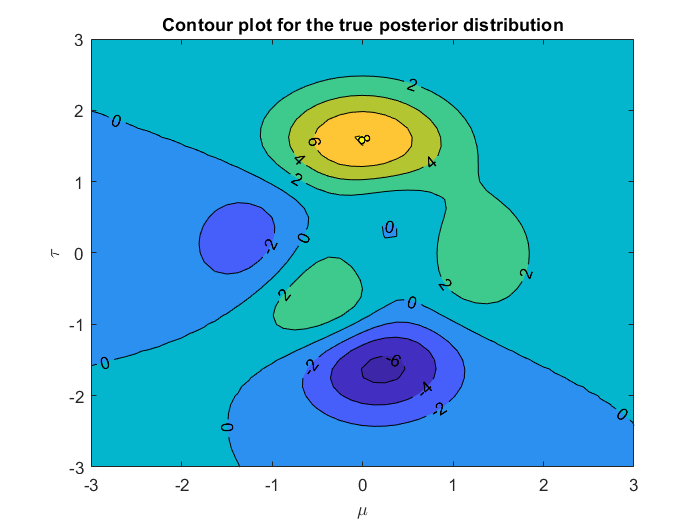

%(a)
mu = linspace(-25,25,50);
taoo = linspace(0,50,50 );
POST = sqrt(lbd*TAO./(2*pi))*exp(-lbd*TAO./2*(MU-m).^2)*b^a*TAO.^(a-1)/gamma(a)*exp(-b*TAO);
[MU,TAO,POST] = peaks;
contourf(MU,TAO,POST,'ShowText','on')
xlabel('\mu');
ylabel('\tau');
title('Contour plot for the true posterior distribution');

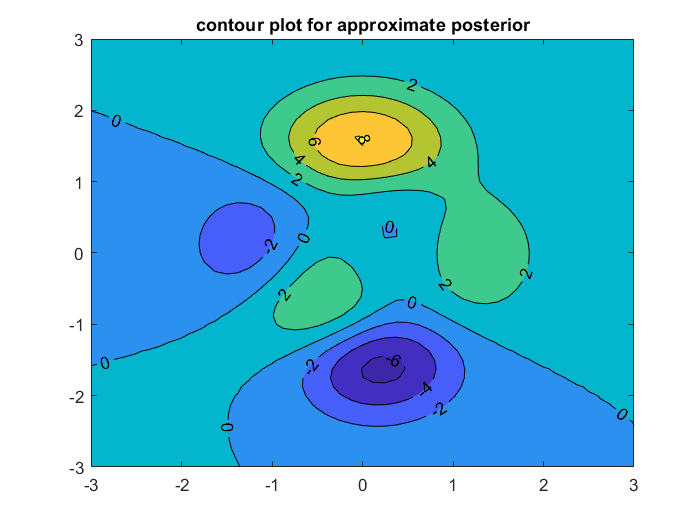

%(b)
S = 1/(a/b*(N+lbd0));
M = (lbd0*mu0+N*y_m)/(lbd0+N);
qmu = 1/(sqrt(2*pi*S))*exp(-1/(2*S)*(MU-M).^2);
aa = a0 + (N+1)/2;
bb = b0 + 0.5*(sum((obs-M).^2)+lbd0*(mu0-M).^2+(N+lbd0)*S);
gamm = bb.^aa*TAO.^(aa-1)/gamma(aa)*exp(-bb*TAO);
POSTT = gamm*qmu;
[MU,TAO,POSTT] = peaks;
contourf(MU,TAO,POSTT,'ShowText','on')
title("contour plot for approximate posterior");